%% Ex 3.2
% clear; clc; close all
% 
% format long
% 
% f = @(x) exp(x);
% syms x
% df = matlabFunction(diff(f(x),x,1));
% x0 = 0;
% h = logspace(-20,0,100);
% 
% %retrograde
% df_r = (f(x0) - f(x0-h))./h;
% %centered
% df_c = (f(x0+h) - f(x0-h))./(2*h);
% 
% F = figure;
% F.PaperUnits = 'centimeters';
% F.PaperSize = [10 10];
% F.PaperPosition = [0 0 10 10];
% 
% 
% semilogx(h, df_r,h,df_c, h, df(x0)*ones(1,length(h)),'--k'); grid on;
% legend("Retrograde", "Centered", "Real value")
% xlabel("h");ylabel("$f'(x_0)$", 'Interpreter','latex')

oef 3.3

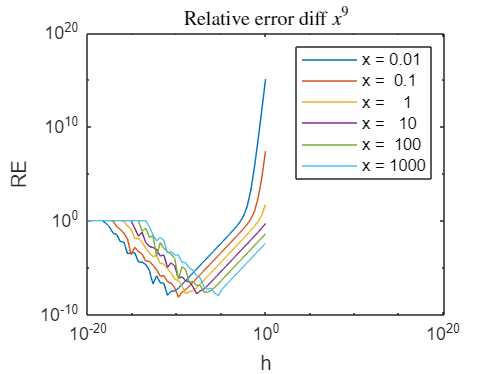

clear; clc; close all
% Theoretical results
x = 10.^(-2:3)';
Ih = logspace(-20,0);

syms s
f = @(x) x.^9;

f1 = matlabFunction(diff(f(s),1));
f2 = matlabFunction(diff(f(s),2));

err_sup = (Ih./2) .* abs(f2(x)) + (2*eps./Ih).*abs(f(x+Ih));
h_opt = 2*sqrt((eps*abs(x.^9))./abs(f2(x)));
h_opt_error = (h_opt./2) .* abs(f2(x)) + (2*eps./h_opt).*abs(f(x+h_opt));

y = zeros(length(x),length(Ih));

y = ((x+Ih).^9 - x.^9)./Ih;
AE = abs(y- 9.*x.^8);
RE = AE./(9.*x.^8);
loglog(Ih,RE)   
axis equal
title("Relative error diff $"+latex(sym(f))+"$", "Interpreter","latex");
legend("x = "+num2str(x))
ylabel("RE"); xlabel("h")

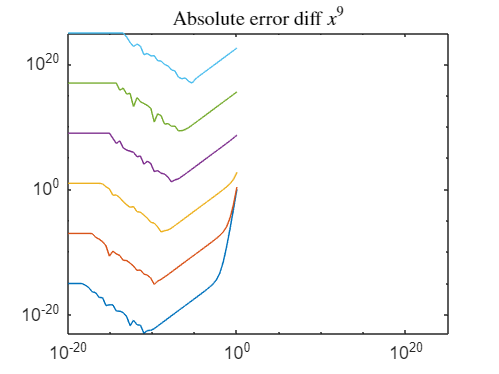

loglog(Ih,AE)
axis equal
title("Absolute error diff $"+latex(sym(f))+"$", "Interpreter","latex");

oef 3.7